# Interpolació inversa

## Aprenem....

Para encontrar un valor intermedio x tal que f(x)=0 en una tabla discreta:

- Metodo 1: Aplicamos interpolacion: Calculamos el polinomio interpolador y resolvemos p(x) = 0.

- Metodo 2: Aplicamos interpolacion inversa: Calculamos la funcion inversa P_i tal que P_i(f(x)) = x   ==>  P_i(0) = x

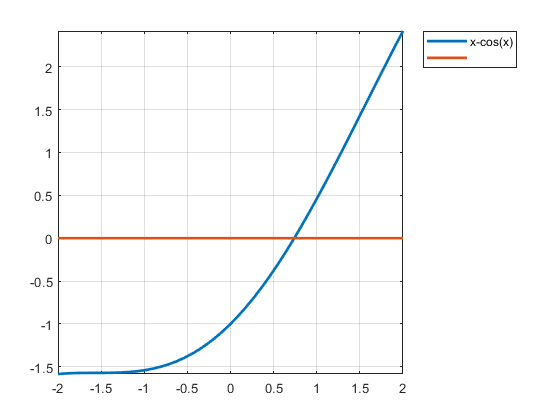

f=@(x)x-cos(x); 
fplot({f,0},[-2,2],'LineWidth',2),grid,legend('Location','bestoutside')

raiz = fzero(f,1)

raiz = 0.7391

xnodes = [-0.5:0.25:1.50];
ynodes = f(xnodes);
disp([xnodes;ynodes]) % Por el teorema de bolzano sabemos que la raiz esta entre 0.5 y 0.75

  Columns 1 through 8

   -0.5000   -0.2500         0    0.2500    0.5000    0.7500    1.0000    1.2500
   -1.3776   -1.2189   -1.0000   -0.7189   -0.3776    0.0183    0.4597    0.9347

  Column 9

    1.5000
    1.4293



alpha = polyinterp(ynodes, xnodes,0) % En que punto queremos calcularlo f(x) = 0

alpha = 0.7390

comparacio = abs(alpha-raiz)

comparacio = 5.9519e-05